## State space model of a buck converter

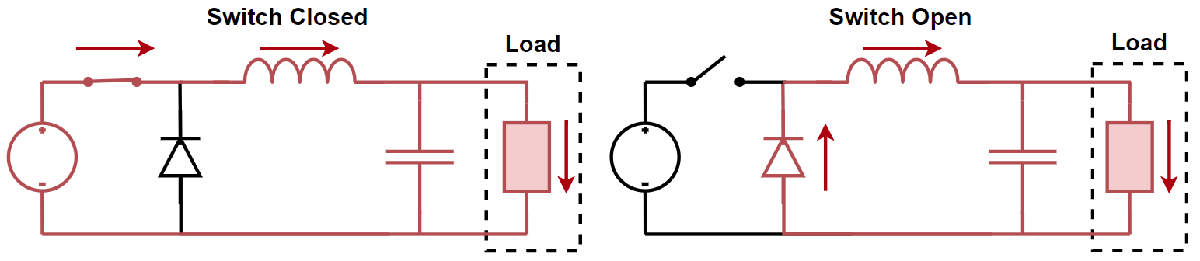

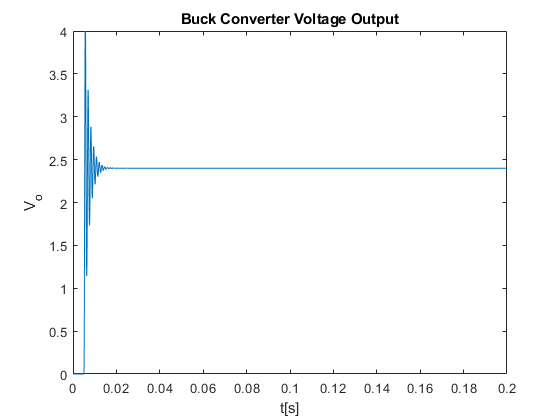

clc;
clear;

% % System variables ---------------------------------------------------------------

R = 100;        % Load Resistor
L = 4.1e-3;     % Inductor
C = 10e-6;      % Capacitor
V_i = 12;       % Input Voltage

% % Set the desired outputs --------------------------------------------------------

V_o = 3;        % Desired output voltage
duty = V_o/V_i; % Duty cycle calculation

% % State matrecies ----------------------------------------------------------------

A = [-1/(R*C), 1/C;
    -1/L,     0];

B = [0,V_i/L]';

C = [0.8, 0];

D = [];

% % System Continuious Time Simulation ---------------------------------------------

sys = ss(A, B, C, D);      % Create the system model

t = 0:0.005/100:0.2;       % Setup the times series
u = zeros(length(t),1);    % Setup the input vector
u(t>0.005) = duty;         % Generate step input of the duty cycle
x_0 = [0, 0, 0]';          % Set initial conditions to zero


[controller, ~] = pidtune(sys, "PI"); % Create a PI controller
sys_controlled = feedback(controller*sys, 1/V_i); % apply the controller to the system
info = stepinfo(sys_controlled);

% % simulate the system in continuious time

[y, t, x] = lsim(sys, u, t, []); 
[y_controlled, t_controlled, x_controlled] = lsim(sys_controlled, u, t, []);

figure()
plot(t, y);
title("Buck Converter Voltage Output");
xlabel('t[s]');
ylabel('V_o');
ylim([0 4])

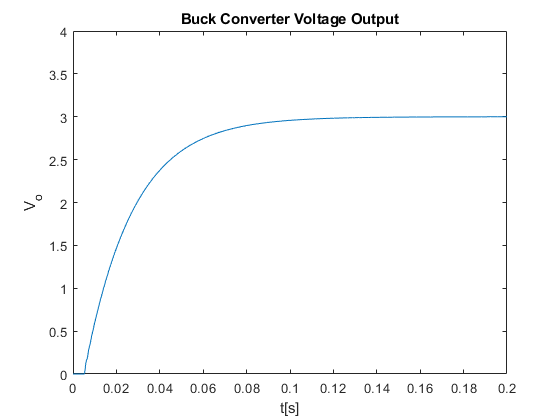


figure()
plot(t_controlled, y_controlled);
title("Buck Converter Voltage Output");
xlabel('t[s]');
ylabel('V_o');
ylim([0 4])

% % System Discrete Time Simulation ---------------------------------------------

ts = 2/100;    % Sampling time period
td = 0:ts:0.5;   % create the samping time series

ud = zeros(length(td), 1);
ud(td >= 0) = duty; % Create the input vector

sysd = c2d(sys, ts);

Kp = 0.16;
Ki = 17.1;

PI_d = pid(Kp,Ki, 0, 0, ts); % Create a PI controller
sysd_control = feedback(PI_d*sysd, 1/V_i);
stepinfo(sysd_control)

ans = struct with fields:
        RiseTime: 0.1200
    SettlingTime: 0.2000
     SettlingMin: 11.1274
     SettlingMax: 12.0000
       Overshoot: 0
      Undershoot: 0
            Peak: 12.0000
        PeakTime: 1.3800


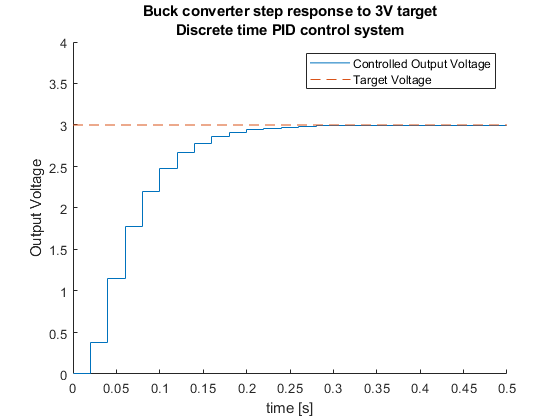

ideal = zeros(1, 26);
ideal(td >= 0) = 3;
[yd, td, xd] = lsim(sysd_control, ud, td, []);


figure()
hold on
stairs(td, yd)
plot(td, ideal, '--')
title(["Buck converter step response to 3V target", "Discrete time PID control system"]);
xlabel('time [s]');
ylabel('Output Voltage');
legend("Controlled Output Voltage", "Target Voltage")
ylim([0 4])
hold off